## 当前坐标系

使用 gca 获得当前活动坐标系

gca

ans =   PolarAxes - 属性:

             ThetaLim: [0 360]
                 RLim: [0 0.5000]
       ThetaAxisUnits: 'degrees'
             ThetaDir: 'counterclockwise'
    ThetaZeroLocation: 'right'

  显示 所有属性


## 绘制线

使用 '线型‘’ 调整线型

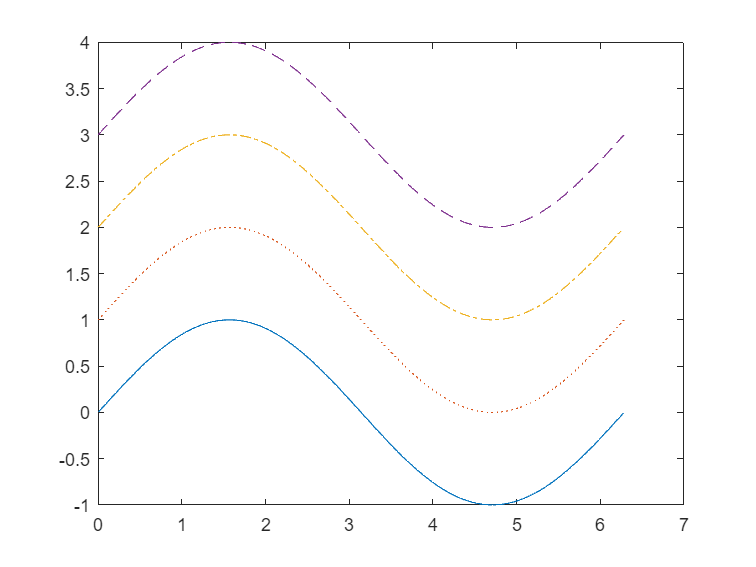

figure;
x = 0:0.01:2*pi;
y = sin(x);
plot(x,y,'-',x,y+1,':',x,y+2,'-.',x,y+3,'--');

使用 '颜色' 调整线颜色

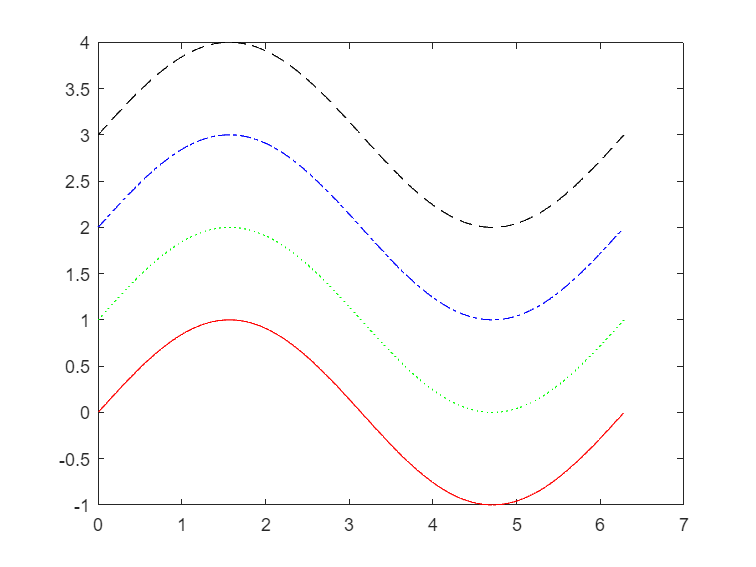

figure;
x = 0:0.01:2*pi;
y = sin(x);
plot(x,y,'r-',x,y+1,'g:',x,y+2,'b-.',x,y+3,'k--');

使用 'LineWidth'  调整线粗

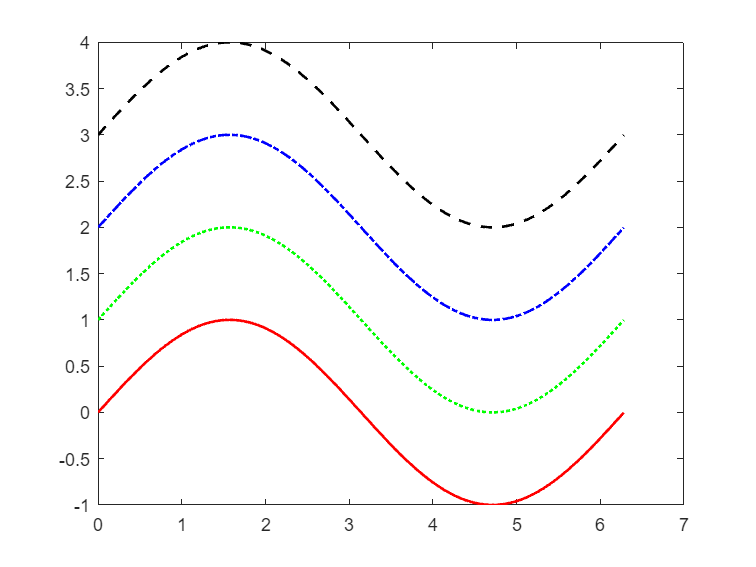

figure;
x = 0:0.01:2*pi;
y = sin(x);
plot(x,y,'r-',x,y+1,'g:',x,y+2,'b-.',x,y+3,'k--','LineWidth',1.5);

## 数据点标记

使用 '标记符号' 调整标记符号

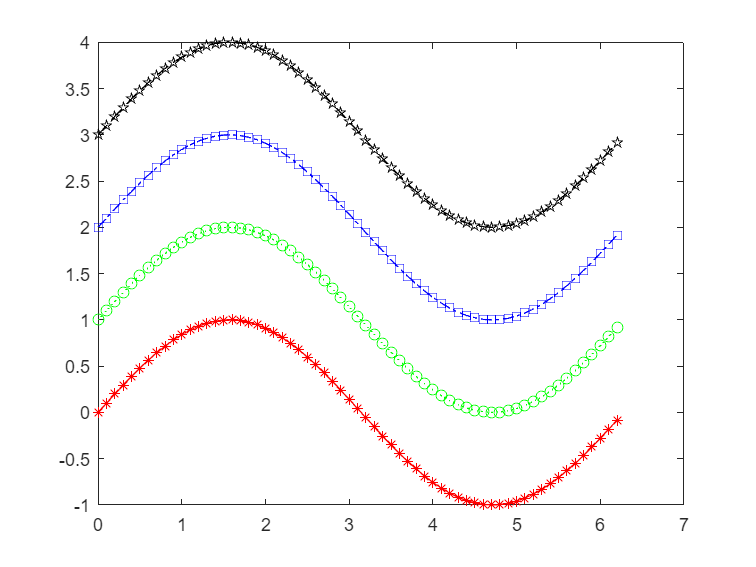

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y,'*r-',x,y+1,'og:',x,y+2,'sb-.',x,y+3,'pk--');

使用 'MarkerSize' 调整标记大小，单位为磅

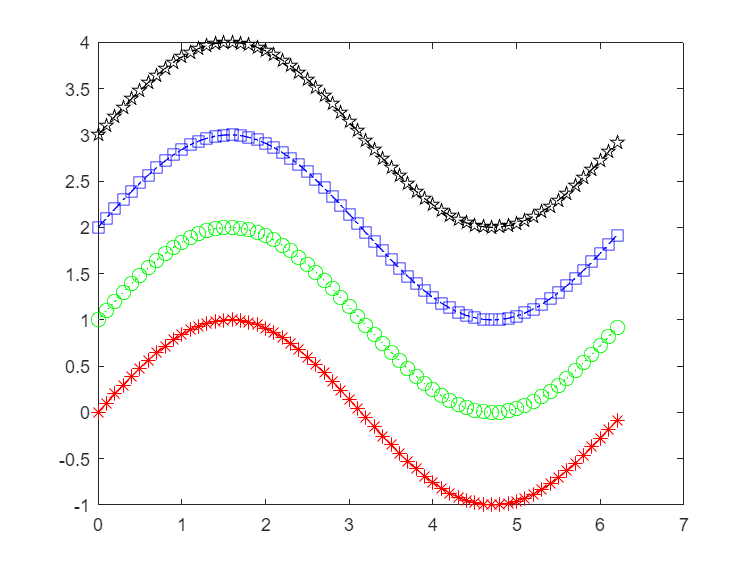

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y,'*r-',x,y+1,'og:',x,y+2,'sb-.',x,y+3,'pk--','MarkerSize',8);

使用 'MarkerEdgeColor' 调整标记轮廓颜色，一幅图只能使用一次，默认为 auto

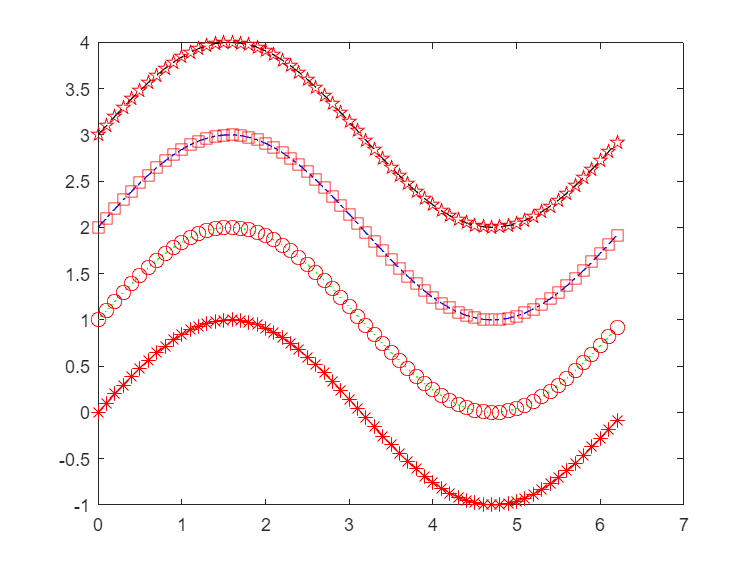

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y,'*r-',x,y+1,'og:',x,y+2,'sb-.',x,y+3,'pk--','MarkerSize',8,'MarkerEdgeColor','r');

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y,'*r-',x,y+1,'og:',x,y+2,'sb-.',x,y+3,'pk--','MarkerSize',8,'MarkerEdgeColor','auto');

使用 'MarkFaceColor' 调整标记填充颜色,一幅图只能使用一次，默认为 none

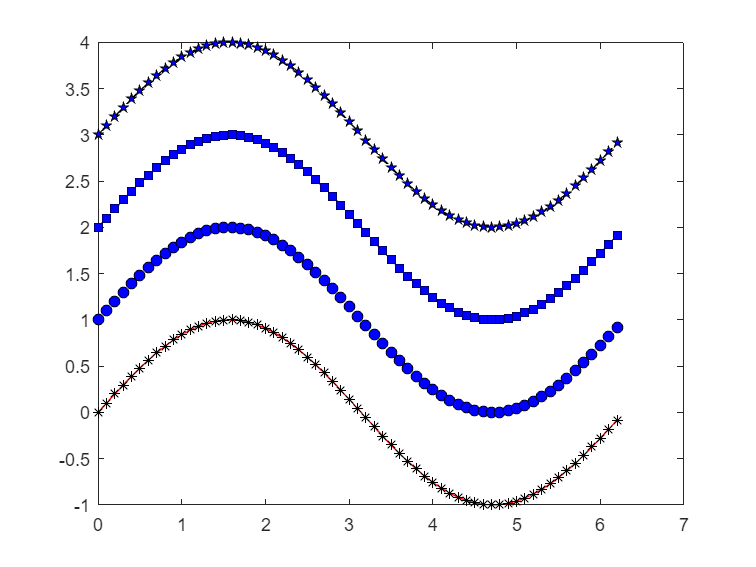

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y,'*r-',x,y+1,'og:',x,y+2,'sb-.',x,y+3,'pk--','MarkerSize',6,'MarkerEdgeColor','k','MarkerFaceColor','b');

## 标题

使用 title('标题') 在当前图窗添加标题

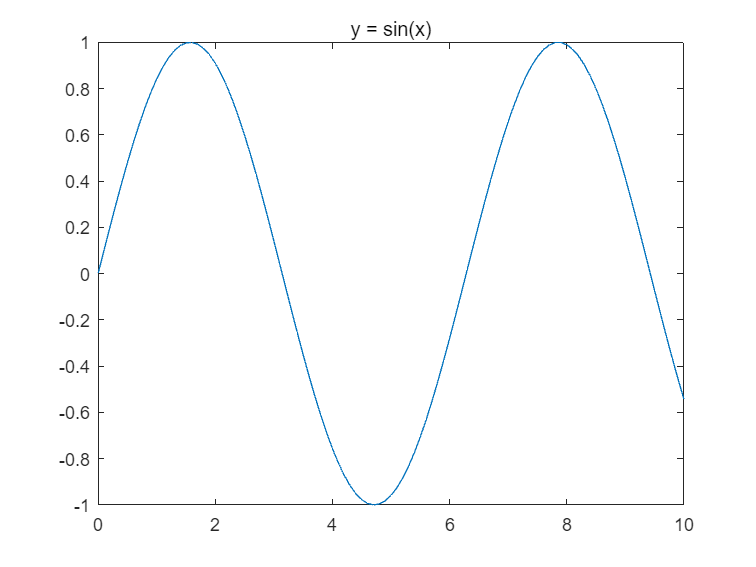

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
title('y = sin(x)');

使用 title('标题','副标题') 在当前图窗添加标题与副标题

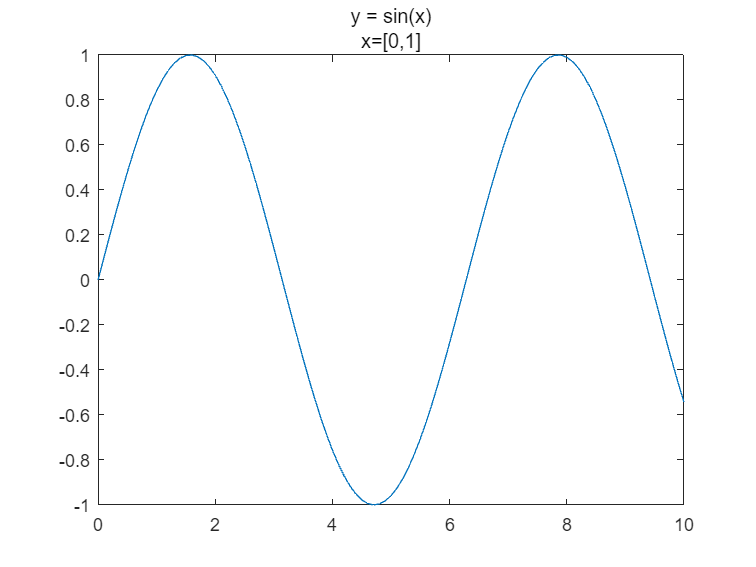

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
title('y = sin(x)','x=[0,1]');

使用多行元胞数组 {} 创建多行标题

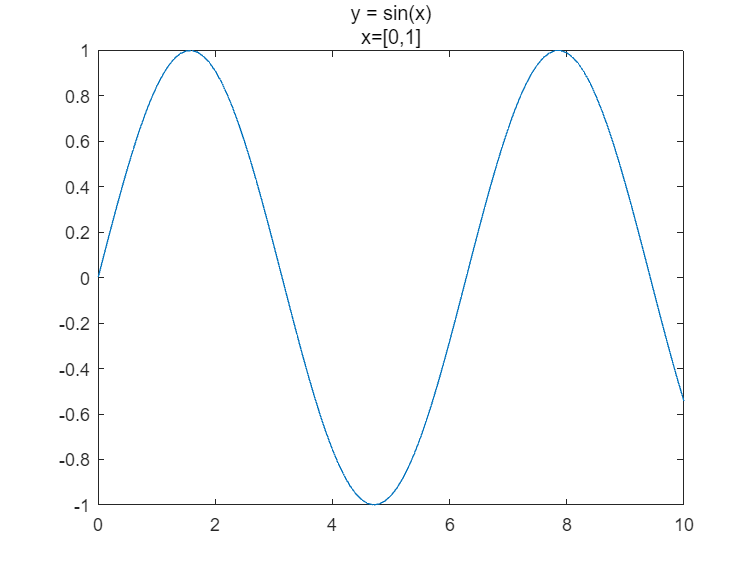

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
title({'y = sin(x)';'x=[0,1]'});

使用 num2str(标题) 在标题包含变量

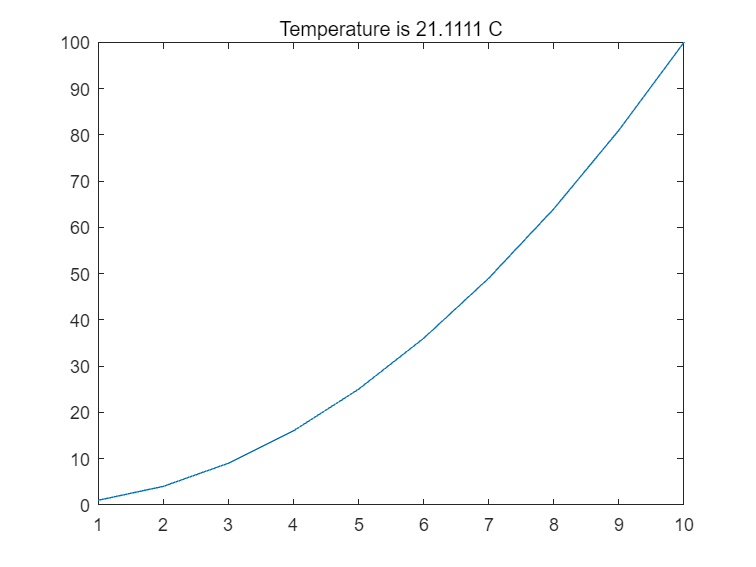

figure
plot((1:10).^2)
f = 70;
c = (f-32)/1.8;
title(['Temperature is ',num2str(c),' C'])

使用 `\color{颜色}` 将其后尾随字符的颜色从先前的颜色更改为新颜色

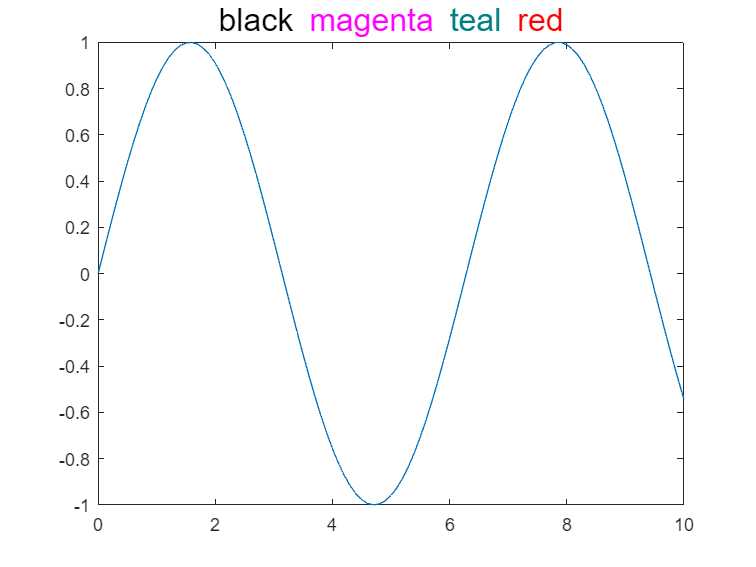

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
title(['\fontsize{16}black {\color{magenta}magenta '...
'\color[rgb]{0 .5 .5}teal \color{red}red}'])

使用 title('标题','Interpreter', 'latex') 使用 Latex 格式，用 $$ 将 Latex 格式的符号括起，不支持中文....

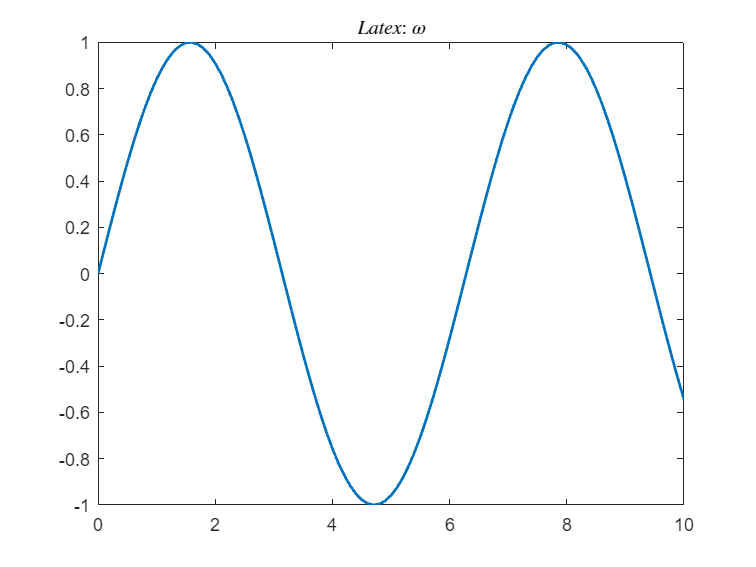

figure;
x = 0:0.1:10;
y = sin(x);
plot(x, y, 'LineWidth', 1.5);
title('$Latex$: $\omega$', 'Interpreter', 'latex');

使用 title('标题','Color',') 调整标题颜色

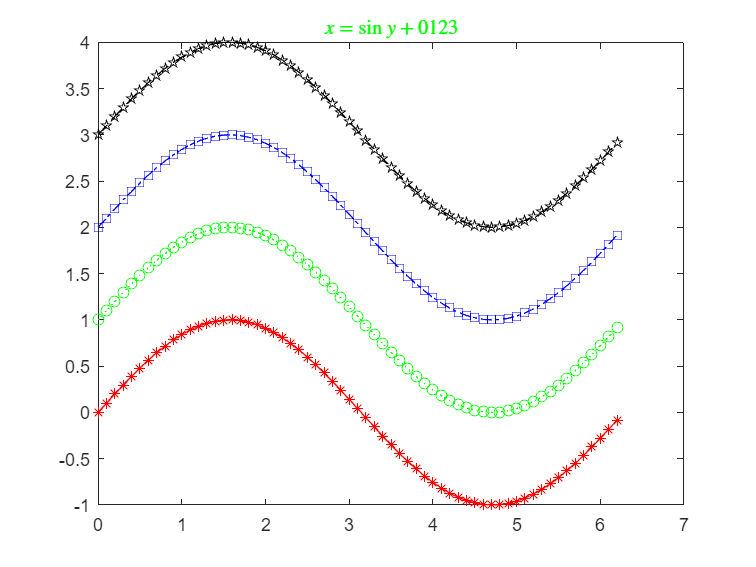

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y,'*r-',x,y+1,'og:',x,y+2,'sb-.',x,y+3,'pk--');
title('$x = \sin{y}+0123$','Interpreter', 'latex','Color','g');

使用 'FontSize' 调整标题字体大小，'FontWeight' 调整标题字体粗细

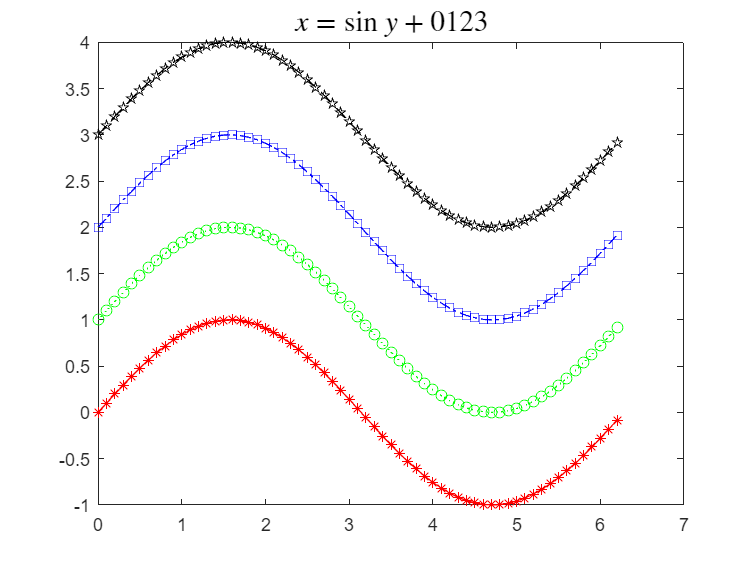

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y,'*r-',x,y+1,'og:',x,y+2,'sb-.',x,y+3,'pk--');
title('$x = \sin{y}+0123$','Interpreter', 'latex','FontSize',16,'FontWeight','bold');

## 坐标轴标签

使用 xlabel('x轴') 给 x 轴加上标签，使用 ylabel('y轴') 给 y 轴加上标签

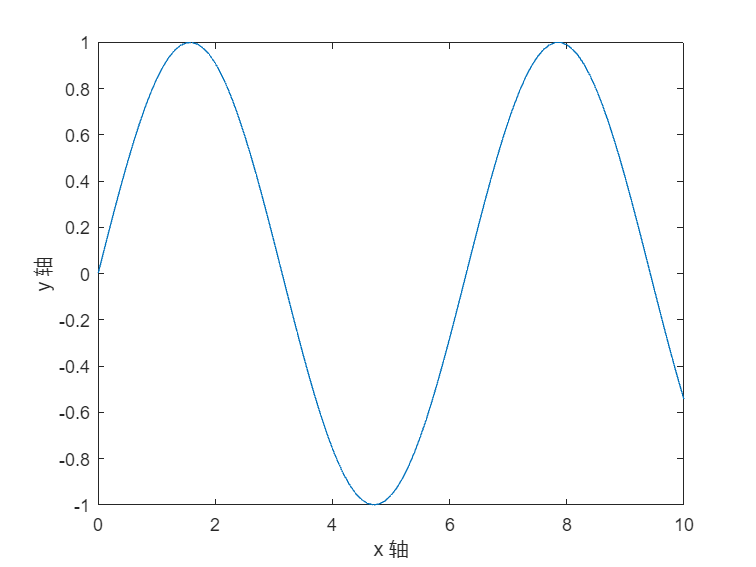

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
xlabel('x 轴');
ylabel('y 轴');

使用字符向量元胞数组创建多行标签

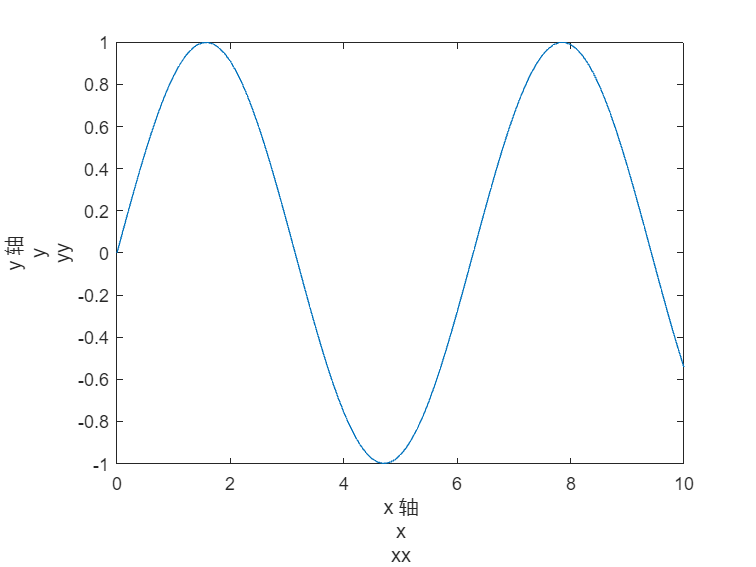

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
xlabel({'x 轴','x','xx'});
ylabel({'y 轴','y','yy'});

使用带有文本和变量值的标签，使用 `num2str` 函数在标签中包含变量值

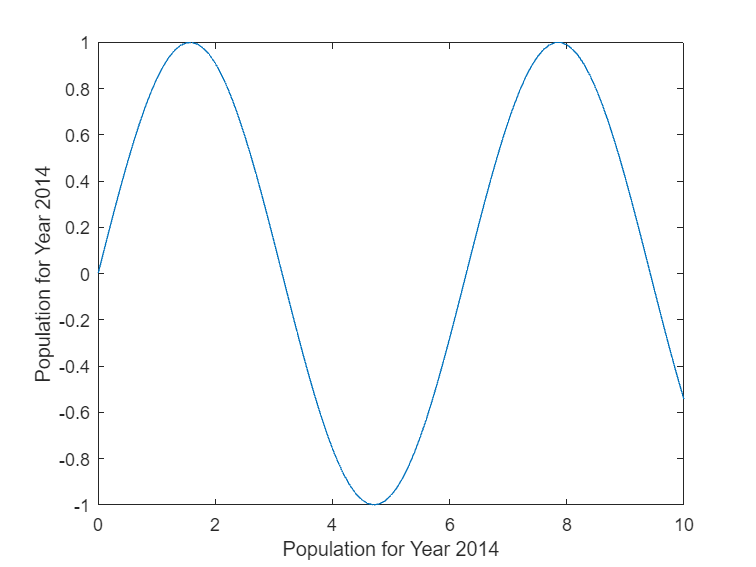

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
year = 2014;
xlabel(['Population for Year ',num2str(year)]);
ylabel(['Population for Year ',num2str(year)]);

使用 xlabel('x轴','Interpreter', 'latex') 使用 Latex 格式，使用 ylabel('y轴','Interpreter', 'latex') 使用 Latex 格式

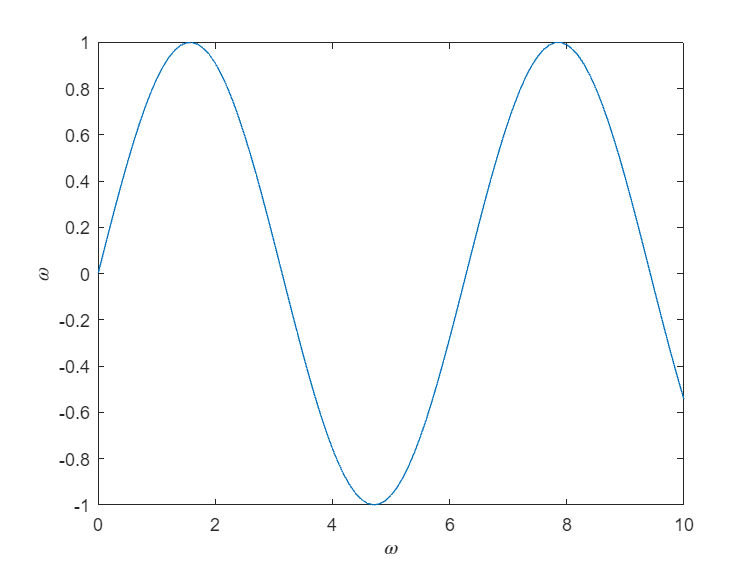

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
xlabel('$\omega$','Interpreter','latex');
ylabel('$\omega$','Interpreter','latex');

使用 'Color' 调整标签颜色

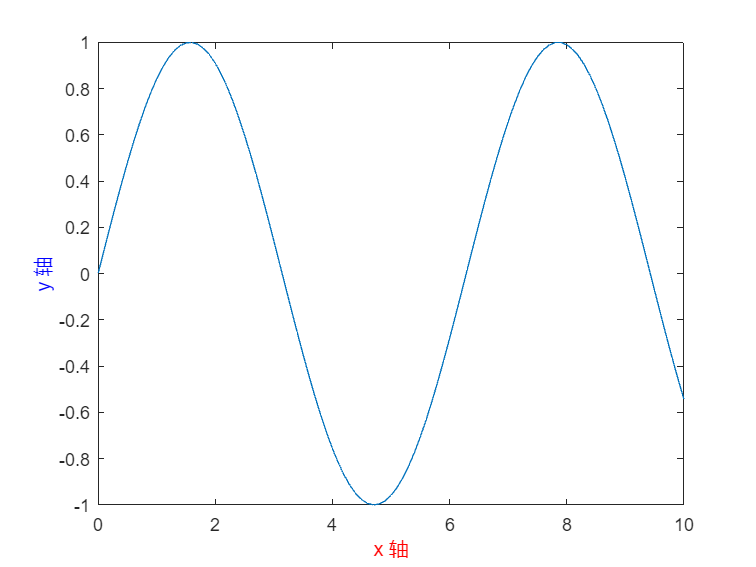

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
xlabel('x 轴','Color','r');
ylabel('y 轴','Color','b');

使用 'FontSize' 调整字体大小，使用 'FontWeight' 调整字体粗细

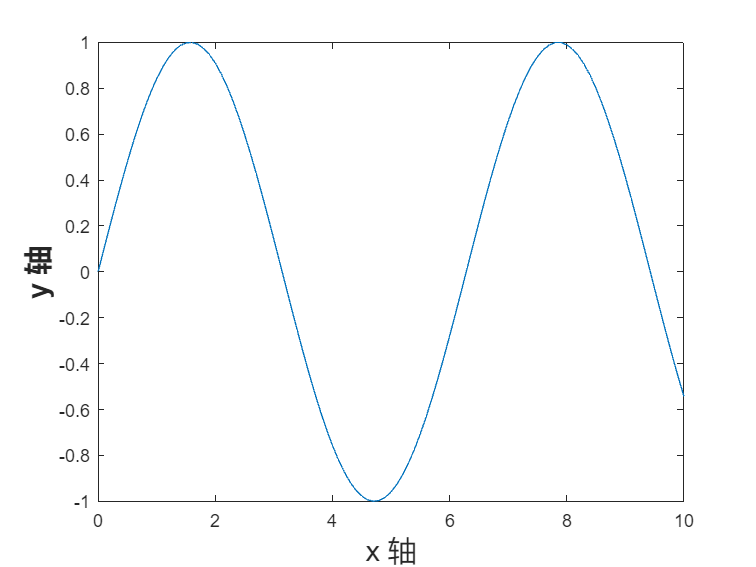

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
xlabel('x 轴','FontSize',16,'FontWeight','normal');
ylabel('y 轴','FontSize',16,'FontWeight','bold');

使用 'Rotation' 调整标签方向，0 度水平，正逆时针负逆时针

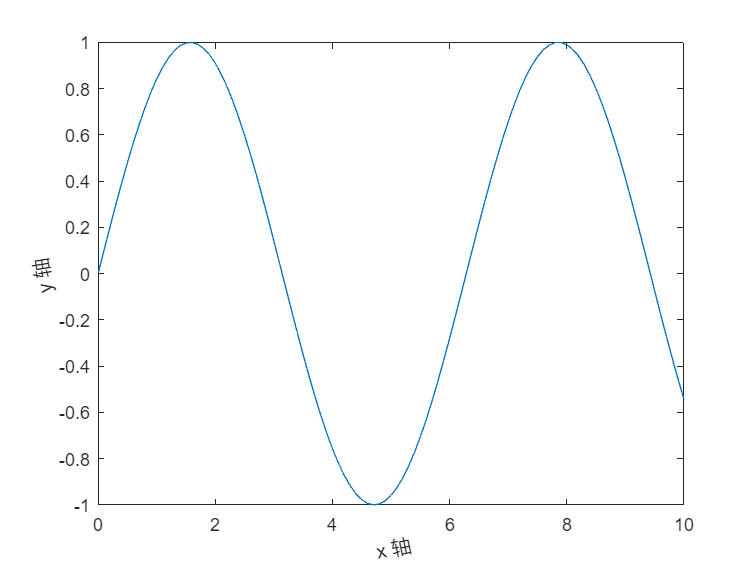

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
xlabel('x 轴','Rotation',12);
ylabel('y 轴','Rotation',99);

## 数据点描述

使用 text(x,y,'描述') 在 x,y 上添加描述

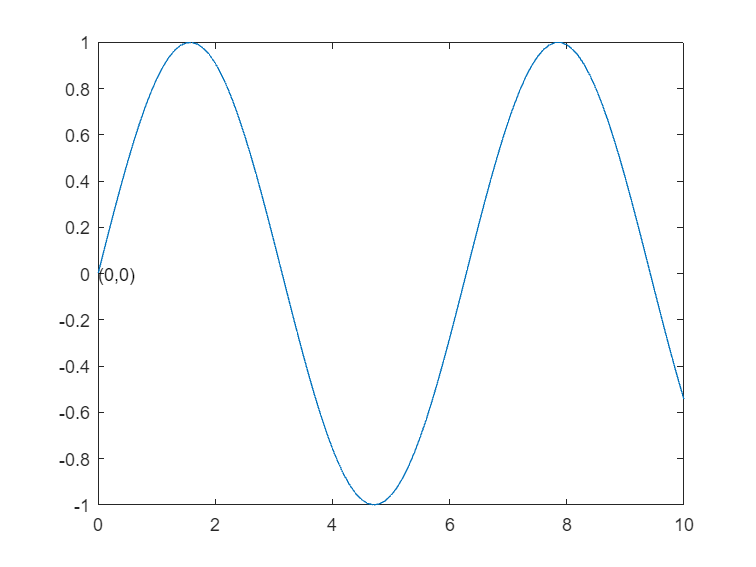

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
text(0,0,'(0,0)');

使用 text(vx,vy,'描述') 在 vx,vy 两个向量对应的数据点上添加描述

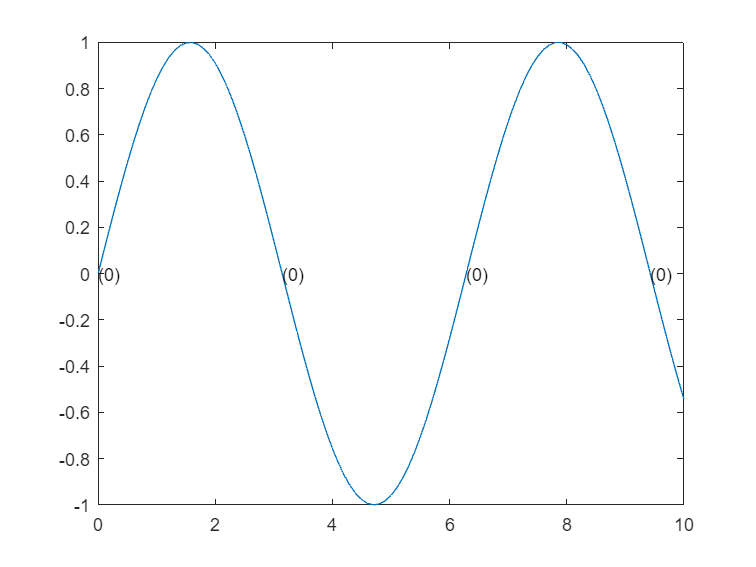

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
vx = 0:pi:10;
vy = sin(vx);
text(vx,vy,'(0)');

使用元胞数组 text(x,y,'描述') 显示多行文本

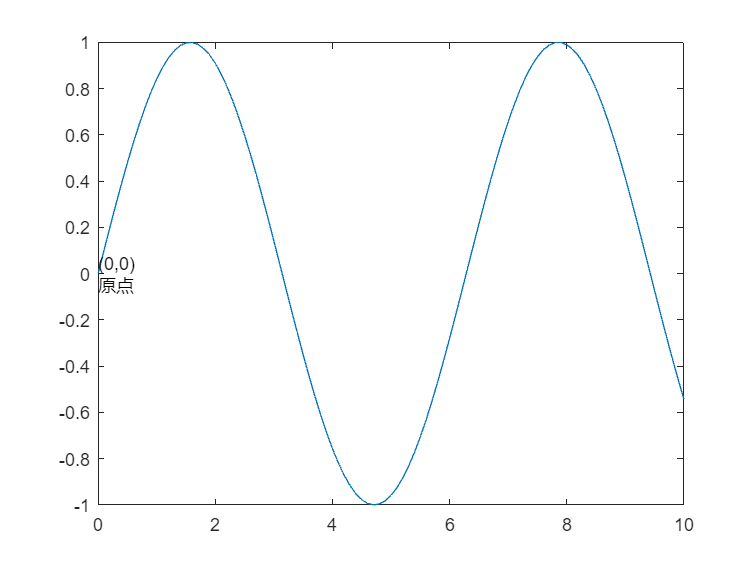

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
text(0,0,{'(0,0)','原点'});

使用 'Color' 调整描述文本

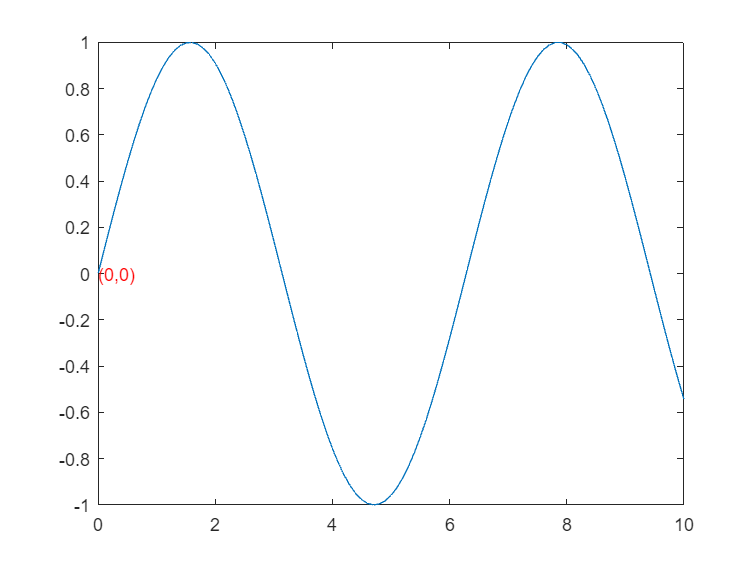

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
text(0,0,'(0,0)','Color','r');

使用 'FontSize' 调整文本大小，使用 'FontSize' 调整文本粗细

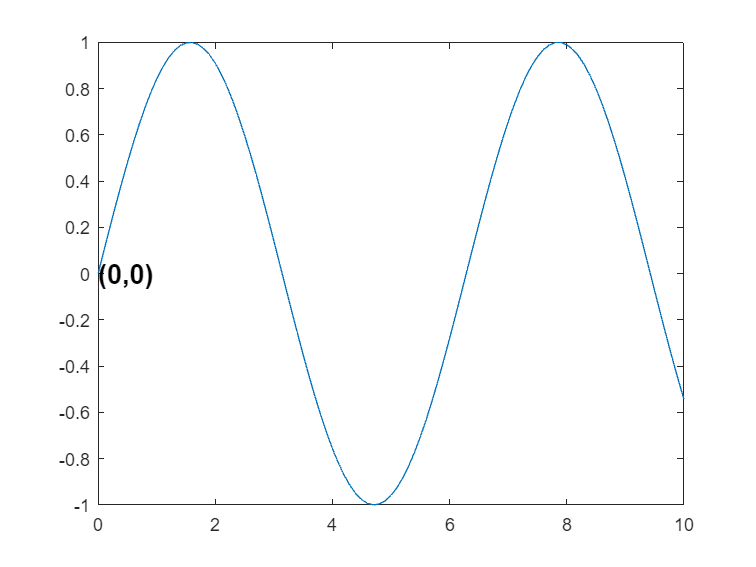

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
text(0,0,'(0,0)','FontSize',15,'FontWeight','bold');

使用 'HorizontalAlignment' 调整文本相对于数据点的位置

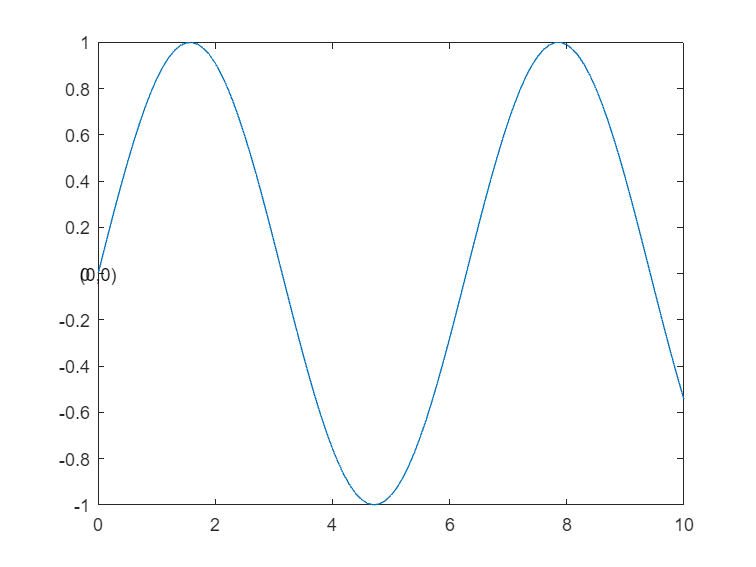

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
text(0,0,'(0,0)','HorizontalAlignment','center');

使用 'interpreter' 使用 Latex 格式

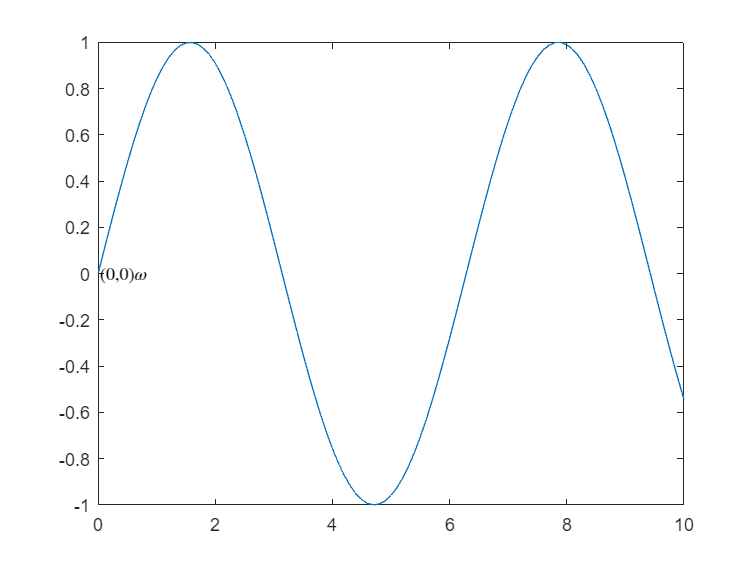

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
text(0,0,'(0,0)$\omega$','Interpreter','latex');

与 text 有同样的属性, gtext('描述') 在创建图后，手动添加描述

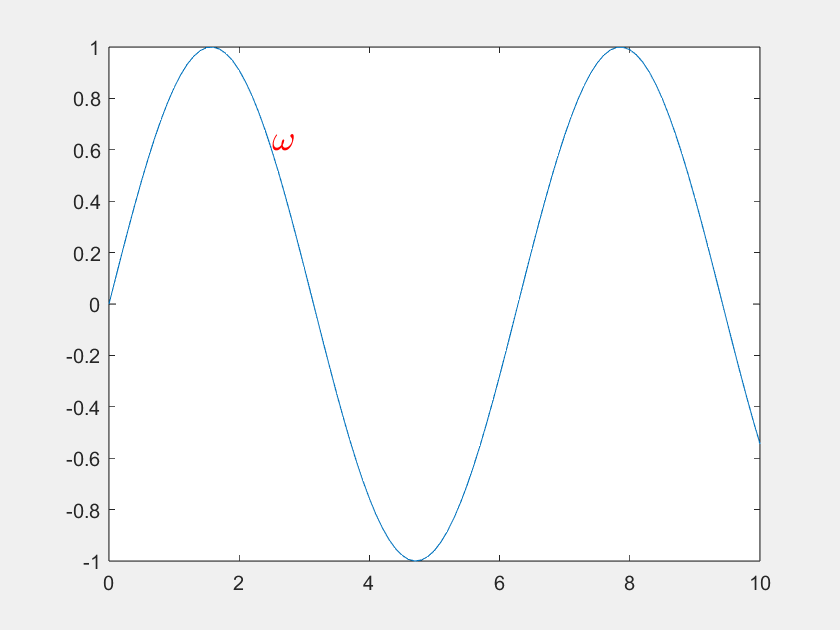

figure;
x = 0:0.1:10;
y = sin(x);
plot(x,y);
gtext('$\omega$','Color','r','Interpreter','latex','FontSize',18,'FontWeight','bold');

## 图例

使用 legend('图例1'，'图例2'...) 给每一个数据序列添加图例

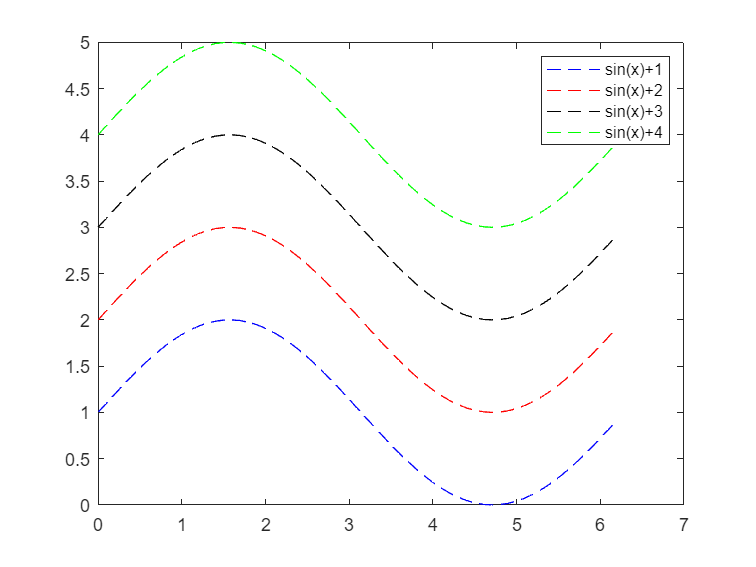

figure;
x = 0:0.1:2*pi;
y1 = sin(x)+1;
y2 = sin(x)+2;
y3 = sin(x)+3;
y4 = sin(x)+4;
plot(x,y1,'b--',x,y2,'r--',x,y3,'k--',x,y4,'g--');
legend('sin(x)+1','sin(x)+2','sin(x)+3','sin(x)+4');

使用 'DisplayName' 在绘图时指定图例标签，在后面使用 legend 来调用图例

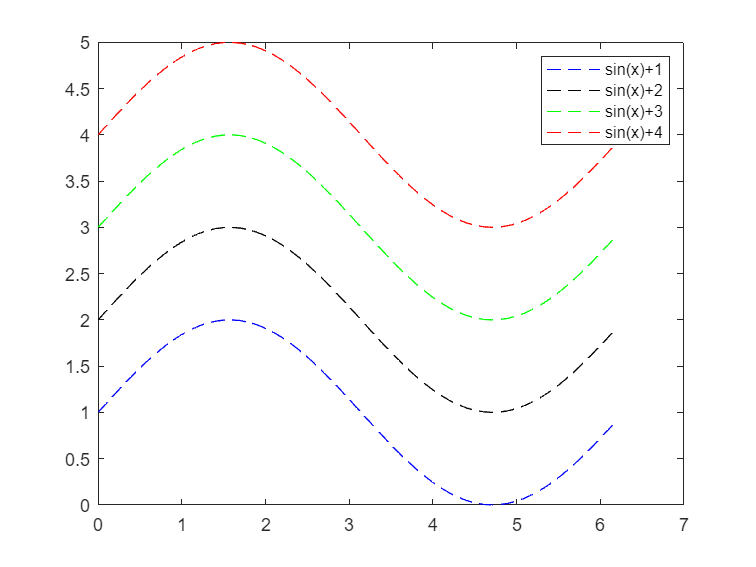

figure;
x = 0:0.1:2*pi;
y1 = sin(x)+1;
y2 = sin(x)+2;
y3 = sin(x)+3;
y4 = sin(x)+4;
plot(x,y1,'b--','DisplayName','sin(x)+1');
hold on
plot(x,y2,'k--','DisplayName','sin(x)+2');
plot(x,y3,'g--','DisplayName','sin(x)+3');
plot(x,y4,'r--','DisplayName','sin(x)+4');
hold off
legend

使用 '' 去除某个线的图例

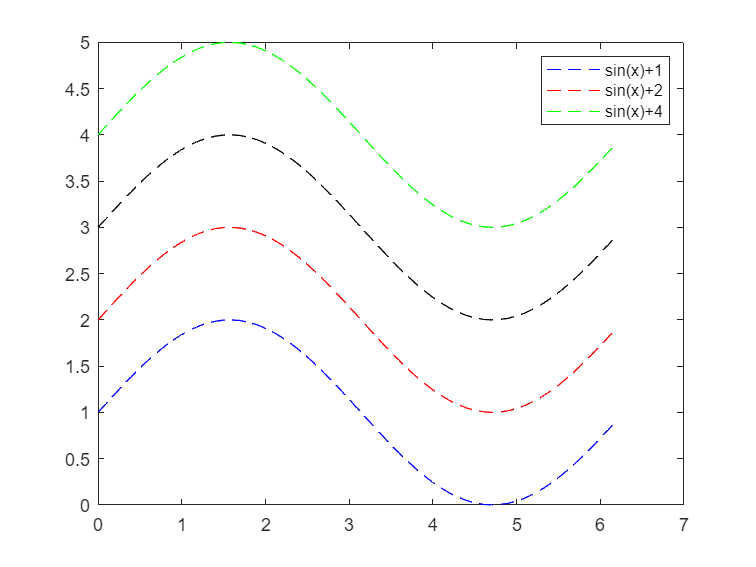

figure;
x = 0:0.1:2*pi;
y1 = sin(x)+1;
y2 = sin(x)+2;
y3 = sin(x)+3;
y4 = sin(x)+4;
plot(x,y1,'b--',x,y2,'r--',x,y3,'k--',x,y4,'g--');
legend('sin(x)+1','sin(x)+2','','sin(x)+4');

使用 'Location' 调整图例位置

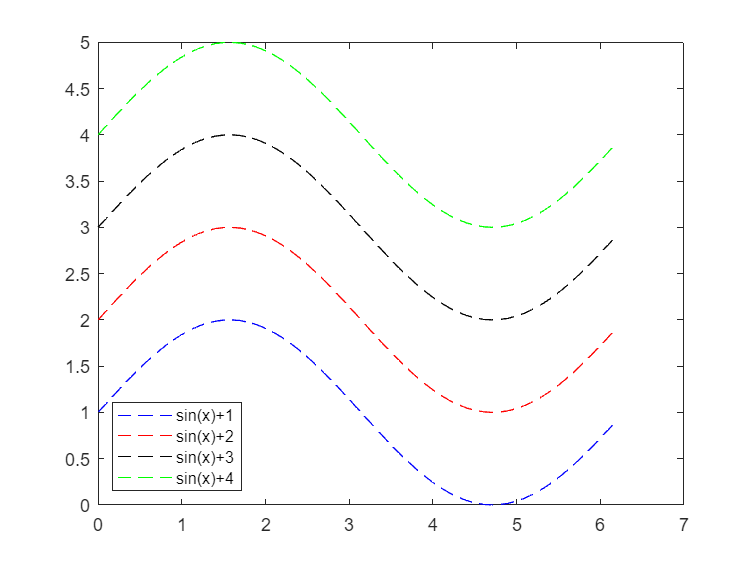

figure;
x = 0:0.1:2*pi;
y1 = sin(x)+1;
y2 = sin(x)+2;
y3 = sin(x)+3;
y4 = sin(x)+4;
plot(x,y1,'b--',x,y2,'r--',x,y3,'k--',x,y4,'g--');
legend('sin(x)+1','sin(x)+2','sin(x)+3','sin(x)+4','Location','southwest');

使用 'interpreter' 使用 Latex 格式

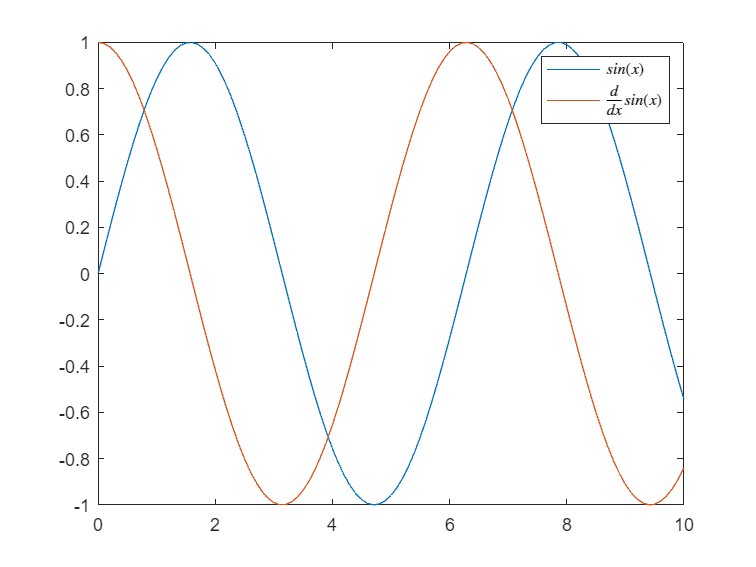

figure;
x = 0:0.1:10;
y = sin(x);
dy = cos(x);
plot(x,y,x,dy);
legend('$sin(x)$','$\frac{d}{dx}sin(x)$','Interpreter','latex');

使用 'TextColor' 调整文本的颜色，使用 'FontSize' 调整文本大小

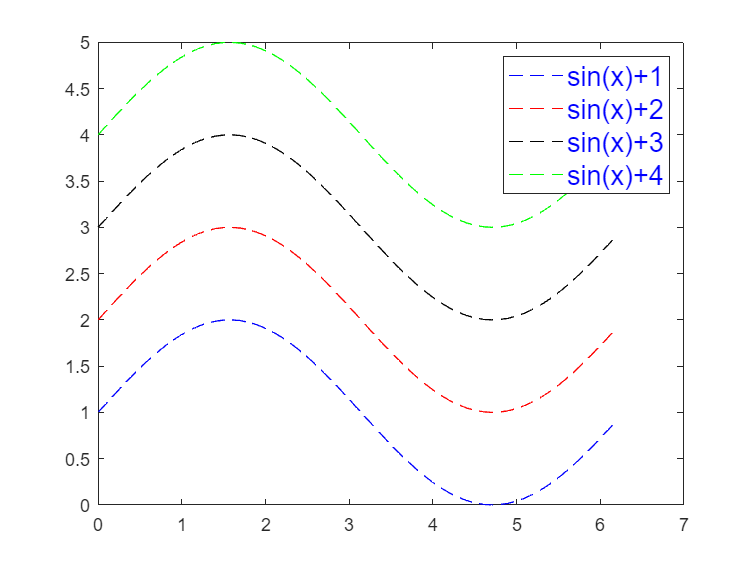

figure;
x = 0:0.1:2*pi;
y1 = sin(x)+1;
y2 = sin(x)+2;
y3 = sin(x)+3;
y4 = sin(x)+4;
plot(x,y1,'b--',x,y2,'r--',x,y3,'k--',x,y4,'g--');
legend('sin(x)+1','sin(x)+2','sin(x)+3','sin(x)+4','TextColor','b','FontSize',15);

## 坐标控制

使用 axis([xmin,xmax,ymin,ymax,zmin,zmax]) 设置坐标范围，没有可省略 z 轴

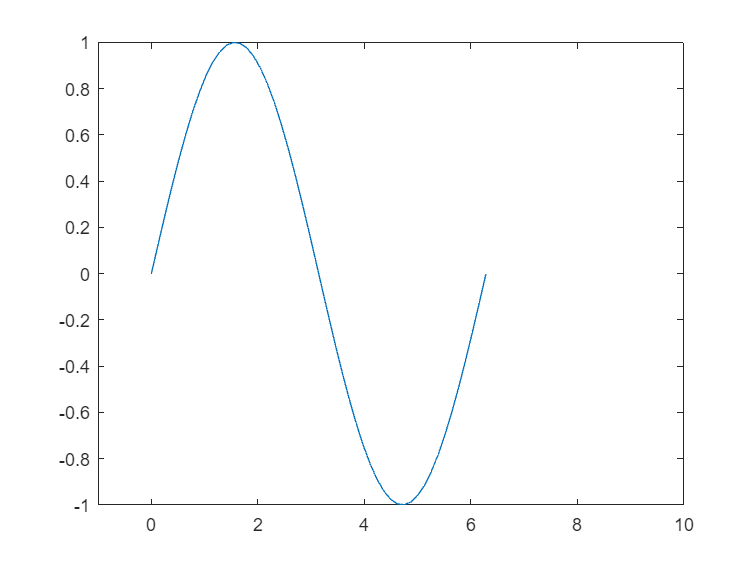

figure;
x = linspace(0,2*pi,50);
y = sin(x);
plot(x,y);
axis([-1,10,-1,1]);

使用 axis 调整坐标轴范围等于数据范围

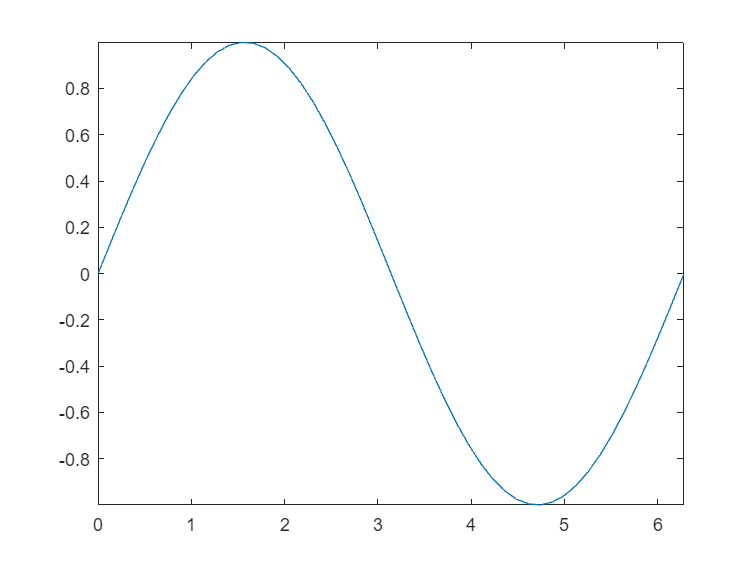

figure;
x = linspace(0,2*pi,50);
y = sin(x);
plot(x,y);
axis tight

使用 axis off 关闭坐标轴，axis on 开启坐标轴

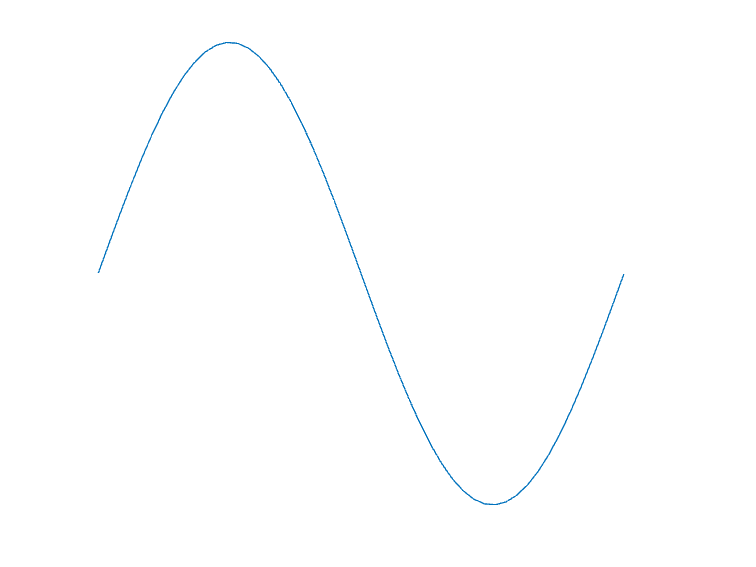

figure;
x = linspace(0,2*pi,50);
y = sin(x);
plot(x,y);
axis off

使用 axis auto 自动调整坐标轴范围

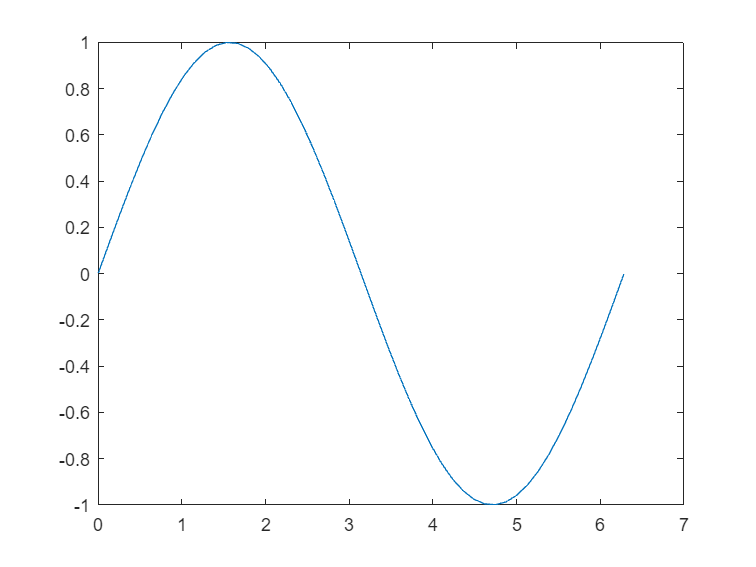

figure;
x = linspace(0,2*pi,50);
y = sin(x);
plot(x,y);
axis auto

## 网格显示

使用 grid on 显示网格，grid off 关闭网格，grid 两者切换

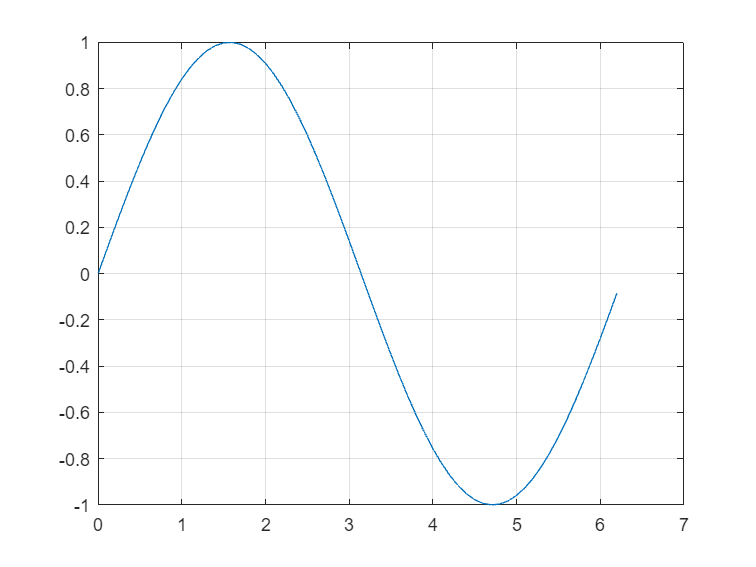

figure;
x = 0:0.1:2*pi;
y = sin(x);
plot(x,y);
grid on

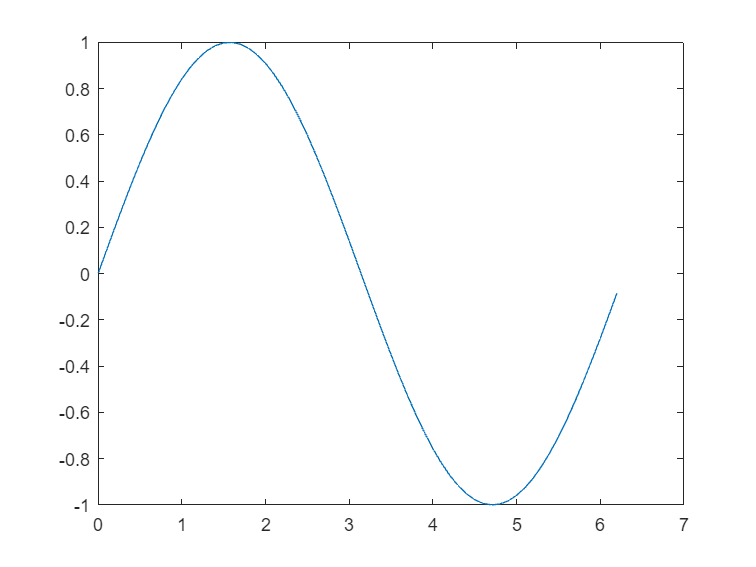

figure;
plot(x,y);
grid off

## 图像保持

使用 hold on 保持图型不被刷新，使用 hold off 关闭，使用 hold 进行切换

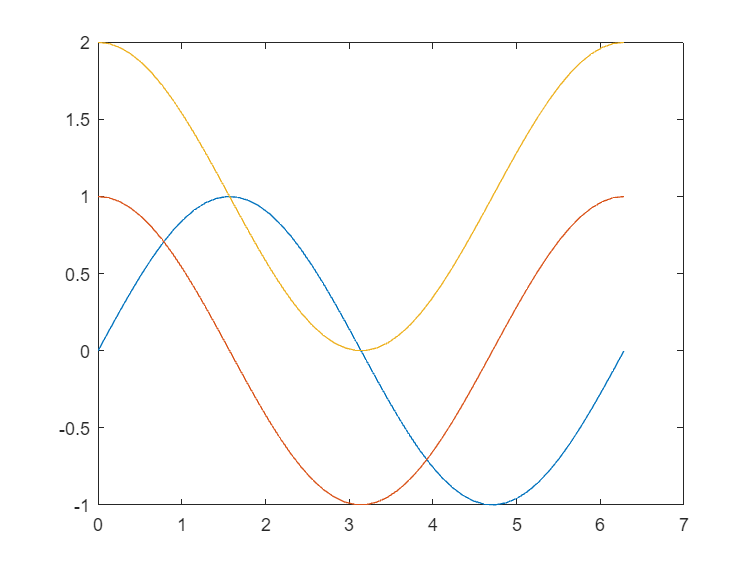

已发布最新绘图


x = linspace(0,2*pi,50);
y1 = sin(x);
y2 = cos(x);
plot(x,y1);
hold on
plot(x,y2);
plot(x,y2+1);
hold

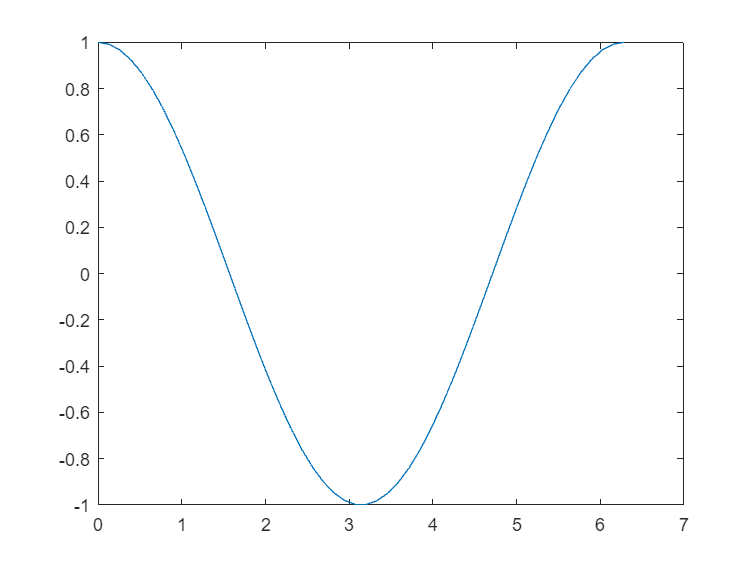

plot(x,y2);

## 窗口切割

使用 subplot(m,n,p) 将其分为 m*n 个绘图区，并指定当前活动区为 p

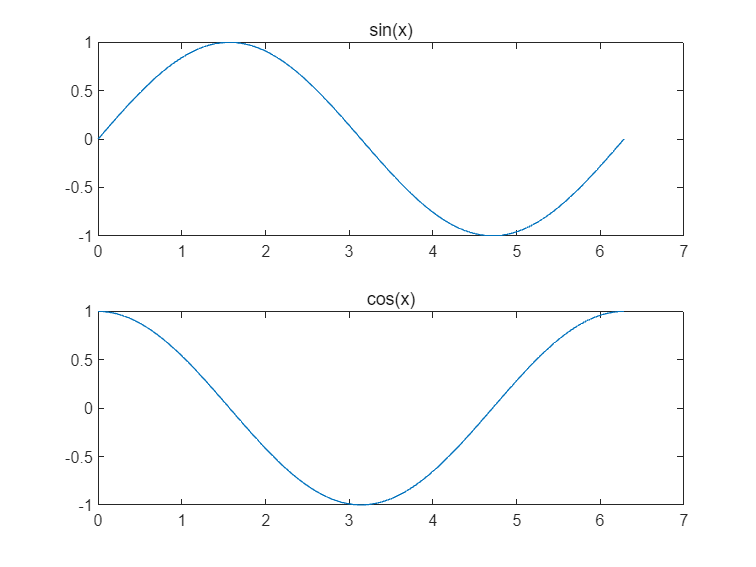

figure;
x = linspace(0,2*pi,100);
y1 = sin(x);
y2 = cos(x);
subplot(2,1,1);
plot(x,y1);
title('sin(x)');
subplot(2,1,2);
plot(x,y2);
title('cos(x)');

使用 [] 使用多个绘图区

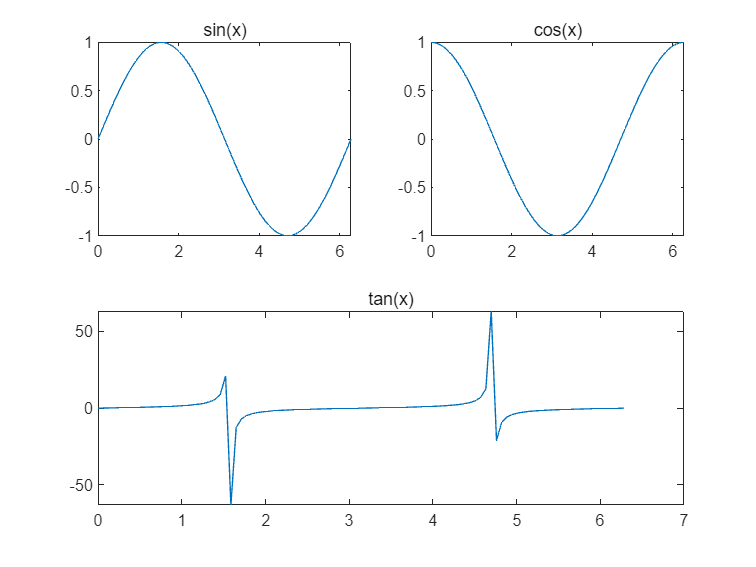

figure;
x = linspace(0,2*pi,100);
y1 = sin(x);
y2 = cos(x);
y3 = tan(x);
subplot(2,2,1);
plot(x,y1);
title('sin(x)');
subplot(2,2,2);
plot(x,y2);
title('cos(x)');
subplot(2,2,[3 4]);
plot(x,y3);
title('tan(x)')

使用 'Position' 自定义图片位置

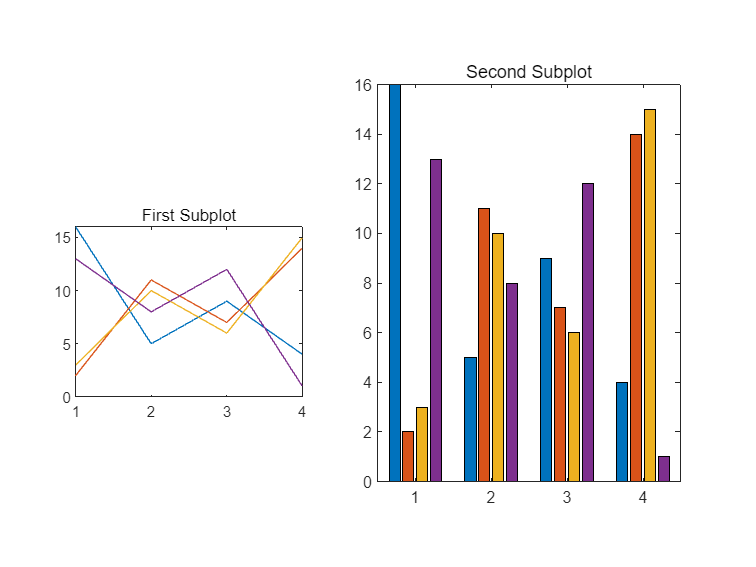

figure;
pos1 = [0.1 0.3 0.3 0.3];
subplot('Position',pos1)
y = magic(4);
plot(y)
title('First Subplot')
pos2 = [0.5 0.15 0.4 0.7];
subplot('Position',pos2)
bar(y)
title('Second Subplot')

使用 polaraxes 创建极坐标分窗口

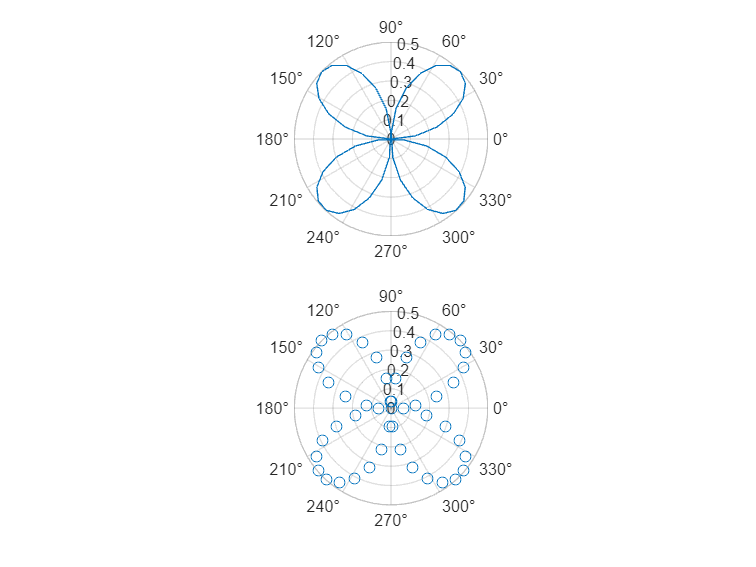

figure
ax1 = subplot(2,1,1,polaraxes);
theta = linspace(0,2*pi,50);
rho = sin(theta).*cos(theta);
polarplot(ax1,theta,rho)
ax2 = subplot(2,1,2,polaraxes);
polarscatter(ax2,theta,rho)

## 创建窗口

使用 figure 创建默认窗口

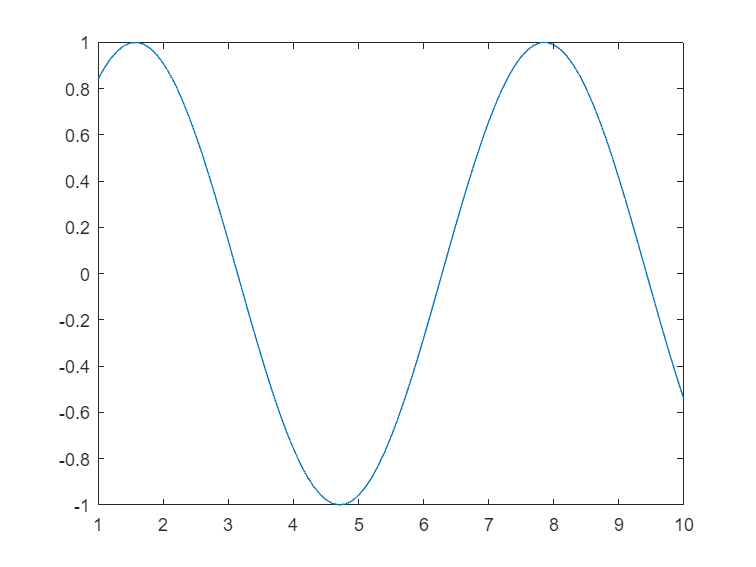

x = 1:0.1:10;
y = sin(x);
f1 = figure;
plot(x,y);

使用 figuer.Position 属性查看 figure 位置、长、宽，可以更改

f2 = figure;
f2.Position

ans =    573   444   560   420


f2.Position(3:4)=[208,210]

f2 =   Figure (87) - 属性:

      Number: 87
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 444 208 210]
       Units: 'pixels'

  显示 所有属性


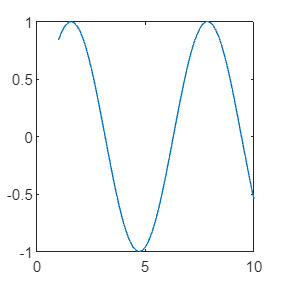

plot(x,y);

使用 figure('Name','标题') 指定图窗标题，包含图窗编号

f3 = figure('Name','我的 figure');
plot(x,y);

使用 figure('Name','标题','Numbertitle','off')  去掉图窗标号

f4 = figure('Name','我的 figure','NumberTitle','off');
plot(x,y);

使用 figure(f) 设置第 f 个 figure 为活动图窗

figure(f4);